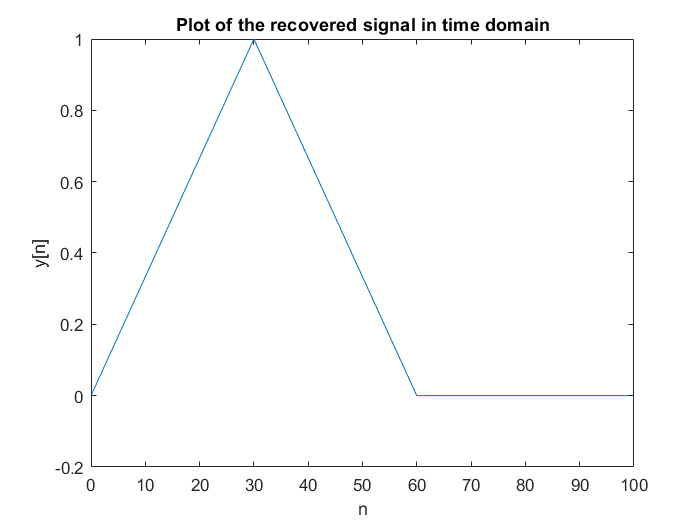

clear all;
close all;
clc;

% DFT for the impulse. 
impulse = zeros(1, 100);
impulse(1) = 1; % Assume the range of x is -49 to 50.  
impulse_fft = fft(impulse);
impulse_fft_mag = abs(impulse_fft);

% DFT for the triangle.
% Triangle signal
x = 0:99;
y = (30 - abs(x-30)) / 30;
y(61:100) = 0;
triangle_fft = fft(y);
triangle_fft_mag = abs(triangle_fft);

% product_of_impulse_and_triangle = triangle_fft_mag .* impulse_fft_mag;
product_of_impulse_and_triangle = impulse_fft .* triangle_fft;
recovered_signal = ifft(product_of_impulse_and_triangle);
x = 0:99;
plot(x, recovered_signal);
xlabel('n');
ylabel('y[n]');
title('Plot of the recovered signal in time domain');


% Circular convolution.


Error using plot
Vectors must be the same length.